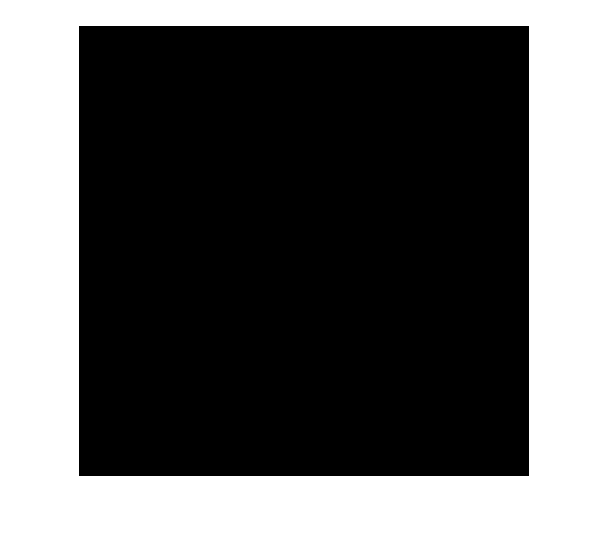

% 512 × 512 pixels の背景画像を作成
imWidth = 512;
imHeight = 512;
im = uint8( zeros(imHeight, imWidth) );
imshow(im);

% pnum 個の粒子の座標を乱数で生成
pnum = 5000;
ppos = rand(pnum, 2) * [imWidth-1 0; 0 imHeight-1] + 1

ppos =   358.0767  131.2137
  375.0208  136.8918
   42.1170  507.2972
  204.7833  286.6849
  472.4072  434.2293
  224.0343  167.5533
  122.2690  121.2831
  117.9347  372.2455
  139.6711   71.3699
  414.9427  301.9918


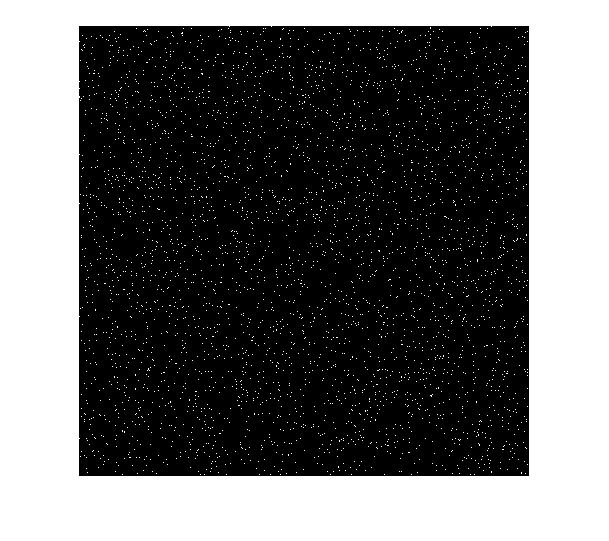

% 粒子座標のピクセルを表示
for i = 1:pnum
im( fix(ppos(i, 2)), fix(ppos(i, 1)) ) = 255;
end
imshow(im);

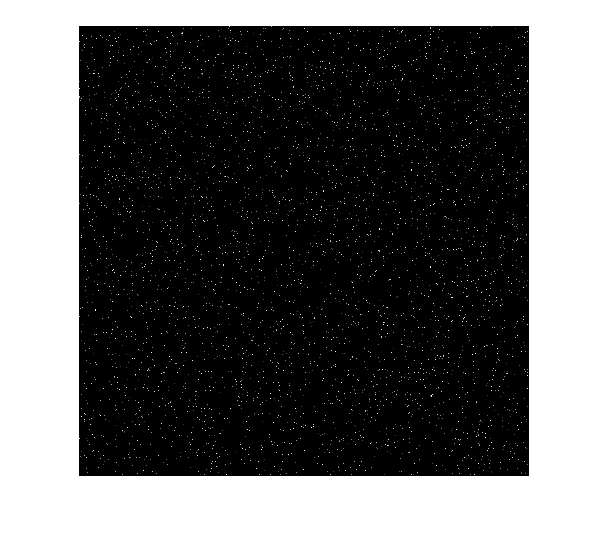

% 粒子の明るさを 50 ‐ 250 の乱数で生成
pbrtMin = 50;
pbrtMax = 250;
pbrt = uint8( (pbrtMax - pbrtMin) .* rand(pnum, 1) + pbrtMin );
for i = 1:pnum
im( fix(ppos(i, 2)), fix(ppos(i, 1)) ) = pbrt(i);
end
imshow(im);

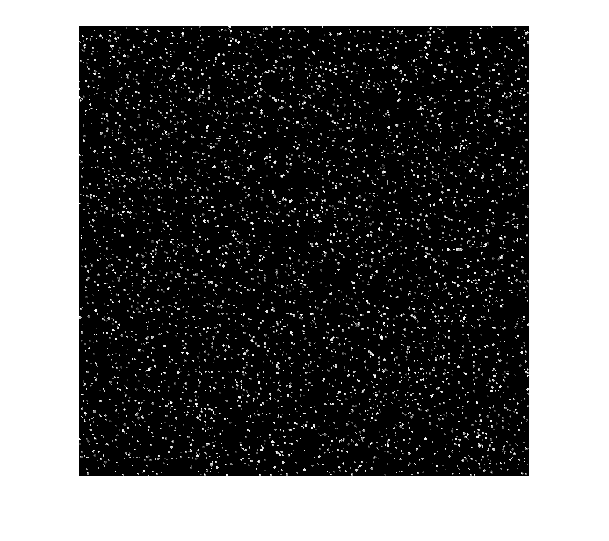

% 粒子の半径を 0.5 ‐ 2 の乱数で生成し、その範囲を中心輝度で塗りつぶす
pradiusMin = 0.5;
pradiusMax = 1.5;
pradius = (pradiusMax - pradiusMin) .* rand(pnum, 1) + pradiusMin;
for m = 1:pnum
for j = -fix(pradius(m)+1) : fix(pradius(m)+1)
for i = -fix(pradius(m)+1) : fix(pradius(m)+1)
r = sqrt( power( fix(ppos(m,1))+i - ppos(m,1) , 2) ...
+ power( fix(ppos(m,2))+j - ppos(m,2) , 2) );
if(r < pradius(m) && ...
fix(ppos(m,1))+i >= 1 && fix(ppos(m,1))+i <= imWidth && ...
fix(ppos(m,2))+j >= 1 && fix(ppos(m,2))+j <= imHeight)
im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) = ...
im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) + pbrt(m);
if(im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) > 255)
im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) = 255;
end
end
end
end
end
imshow(im);

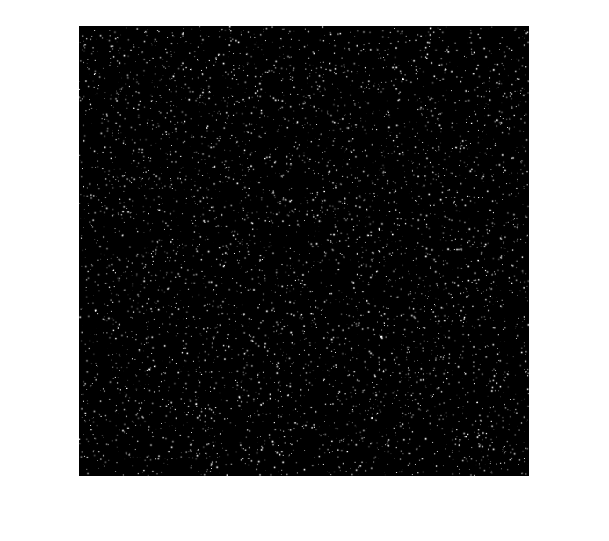

% 粒子の輝度を正規分布に変更
% im の初期化
im = uint8( zeros(imHeight, imWidth) );
for m = 1:pnum
for j = -fix(pradius(m)+1) : fix(pradius(m)+1)
for i = -fix(pradius(m)+1) : fix(pradius(m)+1)
r = sqrt( power( fix(ppos(m,1))+i - ppos(m,1) , 2) ...
+ power( fix(ppos(m,2))+j - ppos(m,2) , 2) );
if(fix(ppos(m,1))+i >= 1 && fix(ppos(m,1))+i <= imWidth && ...
fix(ppos(m,2))+j >= 1 && fix(ppos(m,2))+j <= imHeight)
im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) = ...
im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) + ...
pbrt(m) * exp( -2 * power(r, 2) / power(pradius(m), 2) );
if(im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) > 255)
im( fix(ppos(m,2))+j, fix(ppos(m,1))+i ) = 255;
end
end
end
end
end
imshow(im);

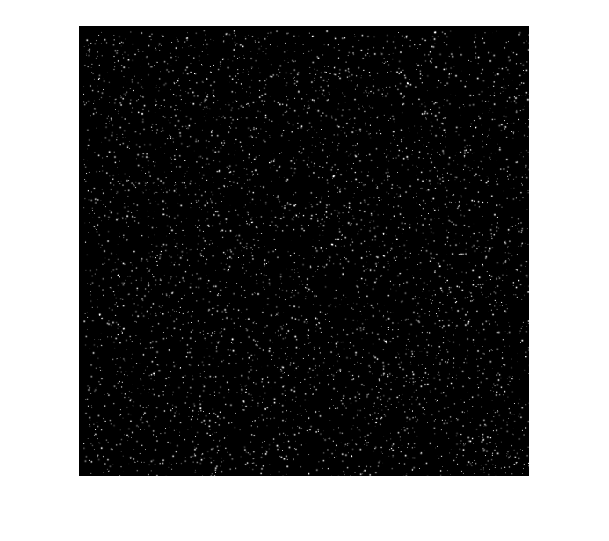

% 移動した粒子画像を作成
pdx = 5.0;
pdy = 5.0;
im2 = uint8( zeros(imHeight, imWidth) );
for m = 1:pnum
for j = -fix(pradius(m)+1) : fix(pradius(m)+1)
for i = -fix(pradius(m)+1) : fix(pradius(m)+1)
r = sqrt( power( fix(ppos(m,1)+pdx)+i - (ppos(m,1)+pdx) , 2) ...
+ power( fix(ppos(m,2)+pdy)+j - (ppos(m,2)+pdy) , 2) );
if(fix(ppos(m,1)+pdx)+i >= 1 && fix(ppos(m,1)+pdx)+i <= imWidth && ...
fix(ppos(m,2)+pdy)+j >= 1 && fix(ppos(m,2)+pdy)+j <= imHeight)
im2( fix(ppos(m,2)+pdy)+j, fix(ppos(m,1)+pdx)+i ) = ...
im2( fix(ppos(m,2)+pdy)+j, fix(ppos(m,1)+pdx)+i ) + ...
pbrt(m) * exp( -2 * power(r, 2) / power(pradius(m), 2) );
if(im2( fix(ppos(m,2)+pdy)+j, fix(ppos(m,1)+pdx)+i ) > 255)
im2( fix(ppos(m,2)+pdy)+j, fix(ppos(m,1)+pdx)+i ) = 255;
end
end
end
end
end
imshow(im2);

% 生成した画像の出力
imwrite(im, "aim0001.bmp");
imwrite(im2, "aim0002.bmp");